## **Laboratorio 4**

## **Modelo Cinemátco Directo**

syms Theta1 Theta2 Theta3 Theta4
T01 = MTH(Theta1,93.3,0,90,2) 

$$T01 = \left(\begin{array}{cccc} \cos\left(\Theta_{1}\right) & 0 & \sin\left(\Theta_{1}\right) & 0\\ \sin\left(\Theta_{1}\right) & 0 & -\cos\left(\Theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{933}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = MTH(Theta2+1.92,0,106.42,0,2)

$$T12 = \left(\begin{array}{cccc} \cos\left(\Theta_{2}+\frac{48}{25}\right) & -\sin\left(\Theta_{2}+\frac{48}{25}\right) & 0 & \frac{5321\,\cos\left(\Theta_{2}+\frac{48}{25}\right)}{50}\\ \sin\left(\Theta_{2}+\frac{48}{25}\right) & \cos\left(\Theta_{2}+\frac{48}{25}\right) & 0 & \frac{5321\,\sin\left(\Theta_{2}+\frac{48}{25}\right)}{50}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = MTH(Theta3+1.22,0,100,0,2) 

$$T23 = \left(\begin{array}{cccc} \cos\left(\Theta_{3}+\frac{61}{50}\right) & -\sin\left(\Theta_{3}+\frac{61}{50}\right) & 0 & 100\,\cos\left(\Theta_{3}+\frac{61}{50}\right)\\ \sin\left(\Theta_{3}+\frac{61}{50}\right) & \cos\left(\Theta_{3}+\frac{61}{50}\right) & 0 & 100\,\sin\left(\Theta_{3}+\frac{61}{50}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34 = MTH(Theta4,0,100,0,2)

$$T34 = \left(\begin{array}{cccc} \cos\left(\Theta_{4}\right) & -\sin\left(\Theta_{4}\right) & 0 & 100\,\cos\left(\Theta_{4}\right)\\ \sin\left(\Theta_{4}\right) & \cos\left(\Theta_{4}\right) & 0 & 100\,\sin\left(\Theta_{4}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Finalmente se puede encontrar el modelo geométrico directo, a través del modelo interno de la cadena cinemática.

T04 = T01*T12*T23*T34

Co1 = [0 0 0 0 0];
NT041 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],Co1(1:4)));
P1 = [NT041(1:3,4);tr2eul(NT041,'deg')']

P1 =  -236.4113
         0
  193.6156
  -90.0000
   90.0000
  -90.0913


Co2 = [25 25 20 -20 0]*(pi/180);
NT042 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],Co2(1:4)));
P2 = [NT042(1:3,4);tr2eul(NT042,'deg')']

P2 =  -214.5972
 -100.0683
   55.8245
  -65.0000
   90.0000
  -65.0913


Co3 = [-35 35 -30 30 0]*(pi/180);
NT043 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],Co3(1:4)));
P3 = [NT043(1:3,4);tr2eul(NT043,'deg')']

P3 =  -220.2063
  154.1901
   88.5440
 -125.0000
   90.0000
  -55.0913


Co4 = [85 -20 55 25 0]*(pi/180);
NT044 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],Co4(1:4)));
P4 = [NT044(1:3,4);tr2eul(NT044,'deg')']

P4 =   -11.5184
 -131.6561
   55.9701
   -5.0000
   90.0000
  -30.0913


Co5 = [80 -35 55 -45 0]*(pi/180);
NT045 = double(subs(T04,[Theta1 Theta2 Theta3 Theta4],Co5(1:4)));
P5 = [NT045(1:3,4);tr2eul(NT045,'deg')']

P5 =   -27.2728
 -154.6716
  204.4514
  -10.0000
   90.0000
 -115.0913


a_i = [0 10.5 10.5 6.5];
alfa_i = [pi/2 0 0 pi/2];
d_i = [8.5 0 0 0];
teta_i = [0 pi/2 pi/2 0];1.75

ans = 1.7500


L(1) = Link('revolute','alpha',alfa_i(1),'a',a_i(1),'d',d_i(1),'offset',teta_i(1),'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',alfa_i(2),'a',a_i(2),'d',d_i(2),'offset',teta_i(2),'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',alfa_i(3),'a',a_i(3),'d',d_i(3),'offset',teta_i(3),'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',alfa_i(4),'a',a_i(4),'d',d_i(4),'offset',teta_i(4),'qlim',[-pi pi]);

q=[0 0 0 0];
ws = [-60 60 -60 60 -30 60];
plot_options = {'workspace',ws,'scale',.9};
Robot = SerialLink(L,'name','Robot','plotopt',plot_options)

 
Robot = 
 
Robot:: 4 axis, RRRR, stdDH, fastRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        8.5|          0|     1.5708|          0|
|  2|         q2|          0|       10.5|          0|     1.5708|
|  3|         q3|          0|       10.5|          0|     1.5708|
|  4|         q4|          0|        6.5|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


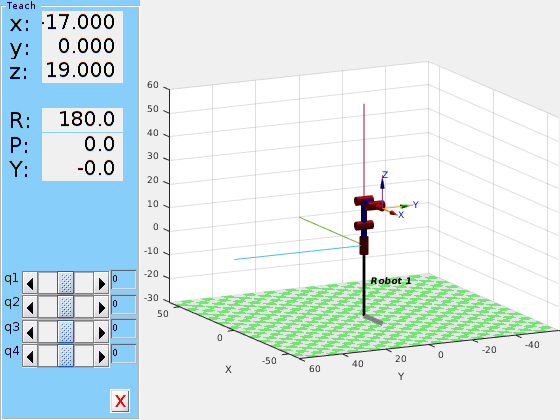

figure
Robot.name = 'Robot 1';
Robot.teach(Co1(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
view([-40 20 10])
hold off

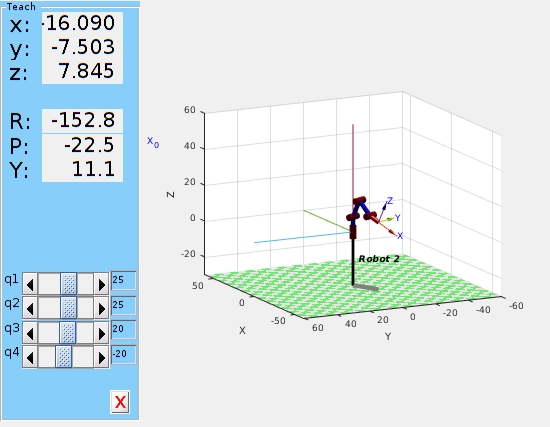

figure
Robot.name = 'Robot 2';
Robot.teach(Co2(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-40 20 10])

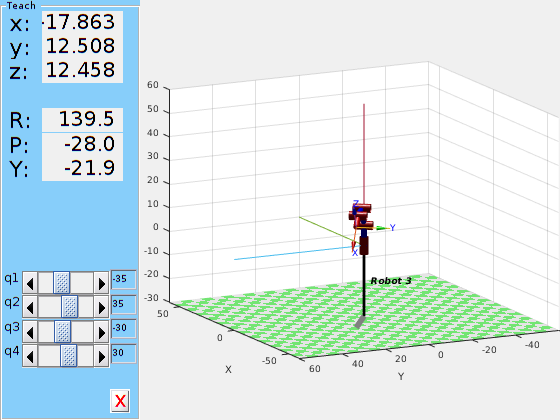

figure
Robot.name = 'Robot 3';
Robot.teach(Co3(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-40 20 10])

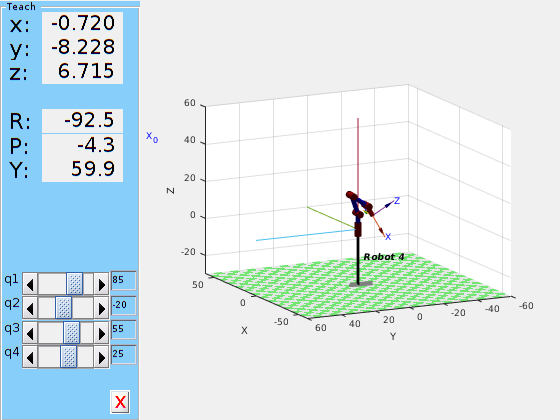

figure
Robot.name = 'Robot 4';
Robot.teach(Co4(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-40 20 10])

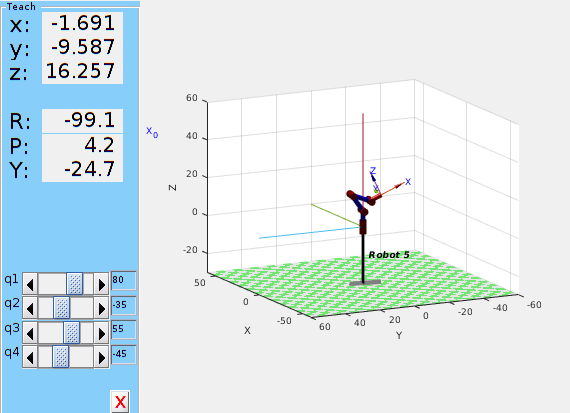

figure
Robot.name = 'Robot 5';
Robot.teach(Co5(1:4));
hold on
trplot(eye(4),'rgb','arrow','length',250,'frame','0') 
hold off
view([-40 20 10])

function [H] = MTH(thetai,di,ai,alphai,angleType)
%Hecho por Andrés Felipe Forero Salas
%Función para calcular la Matriz de Transformación Homogénea
%dados los parámetros DHstd en diferentes posibles sistemas
%numéricos
    if angleType == 0 %rad
        H = [cos(thetai) -sin(thetai)*cos(alphai) sin(thetai)*sin(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cos(alphai) -cos(thetai)*sin(alphai) ai*sin(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai) -sind(thetai)*cosd(alphai) sind(thetai)*sind(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cosd(alphai) -cosd(thetai)*sind(alphai) ai*sind(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 2 %thetai en rad, alphai en degree
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %thetai en degree, alphai en rad
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end